`非对称的多峰光谱。研究双峰间距对白光干涉的测量结果精度的影响，可选磷基LED为参考光谱。通过调整光谱波峰间的间距和峰值比例，分析白光干涉信号峰值凹陷与白光干涉信号峰值的位置关系，`由于近年来照明技术的进步和微机电系统(MEMS)动态表征等新应用的推动，超连续介质光源[1-3]、磷光白光LED[4]、非磷光白光LED[5]、两个低相干光源的组合[6]等现代和混合光源已被用作垂直扫描干涉测量中的光源。无论是基于磷光体的白光led还是基于非磷光体的白光led，都被认为是具有两个不同强度谱峰的双波长白光led。本文模拟了双波长白光LED的光谱特性及其变化规律，研究了其对垂直扫描干涉测量中干涉信号的影响。通过这样做，我们可以利用双波长白光LED的光谱特性来提高垂直扫描干涉测量中基于相位的高度重建算法的性能。

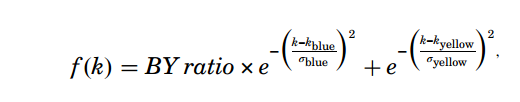

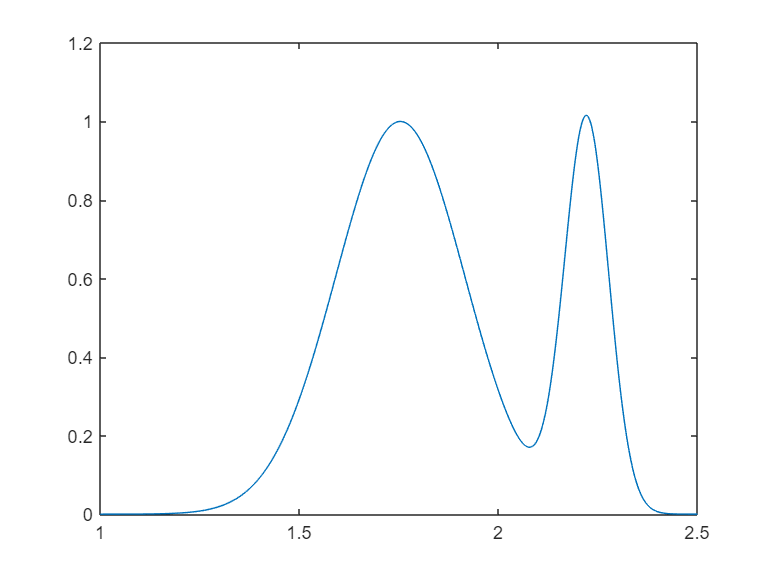




clc;clear all;
k_blue = 13.96;
k_yellow = 11.02;
sigma_blue = 0.4941;
sigma_yellow = 1.439;
BYration = 1;
wavenumber = linspace(1,2.5,1024);
guass = BYration*exp(-((2*pi*wavenumber-k_blue)/sigma_blue).^2)+exp(-((2*pi*wavenumber-k_yellow)/sigma_yellow).^2);
plot(wavenumber,guass);

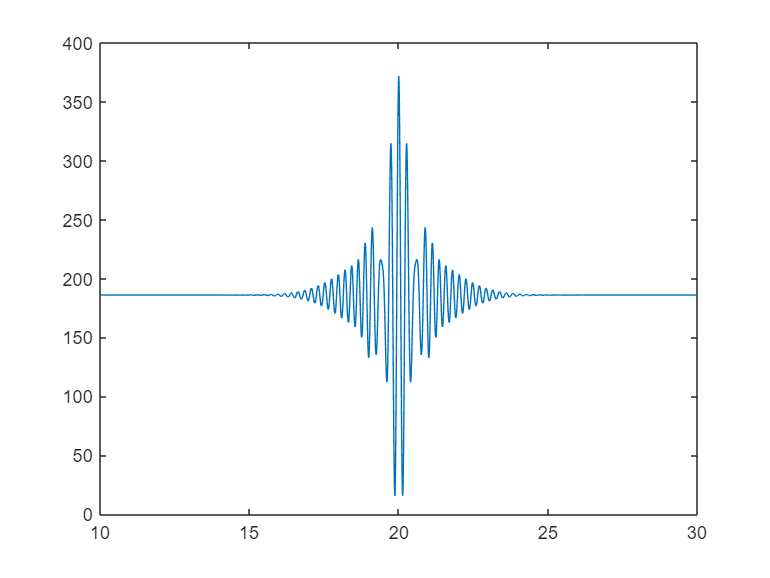

%生成非对称的多峰光谱
z0 = 20;    %单位为微米
N = 40000;
z = 10:30/40000:(N-1)*(30/40000);
spectrum_frequency = wavenumber;
spectrum_intensity = guass;
interference_signal = zeros(1,length(z));
for i = 1:length(z)
        interference_signal(i) = sum(spectrum_intensity./2+...
        spectrum_intensity./2.*cos(4*pi*(z(i)-z0).*(spectrum_frequency)));
end
% disp("生成的白光干涉信号");
plot(z,interference_signal);

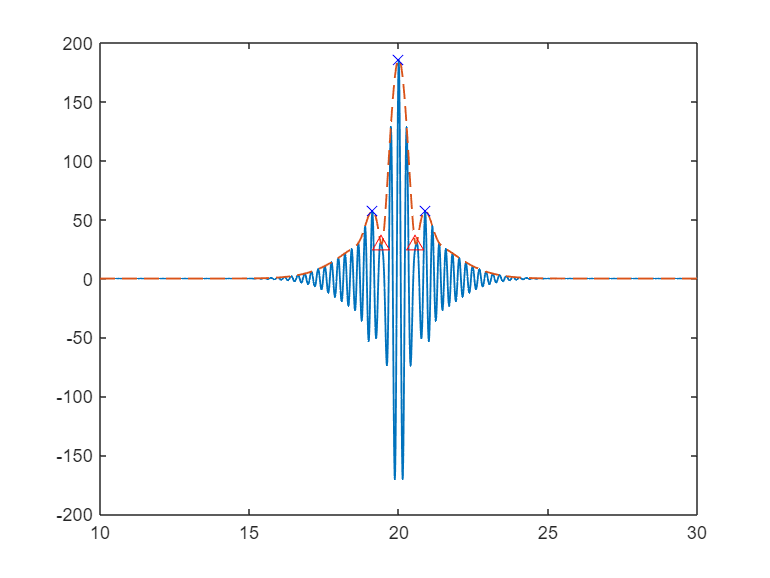

interference_signal = interference_signal-mean(interference_signal);
baoluo = hilbert(interference_signal); % Hilbert变换
baoluo = abs(baoluo);
plot(z,interference_signal,z,baoluo,'--','linewidth',1);
IndMin=find(diff(sign(diff(baoluo)))>0)+1;
IndMax=find(diff(sign(diff(baoluo)))<0)+1;
idx1 = find(z(IndMax)>15 & z(IndMax)<25);
idx2 = find(z(IndMin)>15 & z(IndMin)<25);
IndMax = IndMax(idx1);
IndMin = IndMin(idx2);
hold on
plot(z(IndMax),baoluo(IndMax),'xb','MarkerSize',8)
plot(z(IndMin),baoluo(IndMin),'^r','MarkerSize',8)
hold off


%生成非对称的多峰光谱
clc;clear all;
bofengloc = zeros(70,3);
boguloc = zeros(70,2);
bofeng = zeros(70,3);
bogu = zeros(70,2);
for n = 1:70
k_blue = 13.96;
k_yellow = 11.02;
sigma_blue = 0.4941;
sigma_yellow = 1.439;
BYration = 0.6+0.1*n;
wavenumber = linspace(1,2.5,1024);
guass = BYration*exp(-((2*pi*wavenumber-k_blue)/sigma_blue).^2)+exp(-((2*pi*wavenumber-k_yellow)/sigma_yellow).^2);
plot(wavenumber,guass);
%生成非对称的多峰光谱
z0 = 20;    %单位为微米
N = 40000;
z = 10:30/40000:(N-1)*(30/40000);
spectrum_frequency = wavenumber;
spectrum_intensity = guass;
interference_signal = zeros(1,length(z));
for i = 1:length(z)
        interference_signal(i) = sum(spectrum_intensity./2+...
        spectrum_intensity./2.*cos(4*pi*(z(i)-z0).*(spectrum_frequency)));
end
% disp("生成的白光干涉信号");
% plot(z,interference_signal);

双波长白光LED的使用引入了一个显著特征，这意味着条纹对比度函数不能被建模为单个高斯函数，而显著特征可能会对测量结果产生负面影响。由`非对称的双峰光谱生成的白光干涉信号会在白光干涉信号峰值两侧形成凹陷，这导致在峰值两侧存在一个波峰和波谷。存在的特征：波峰的位置和波峰与峰值比值的变化，波谷的位置和幅度比值。当BYration(蓝光和黄光比值)从0.6到7.6，：波峰的位置和波峰与峰值比值的变化，波谷的位置和幅度比值如下。`

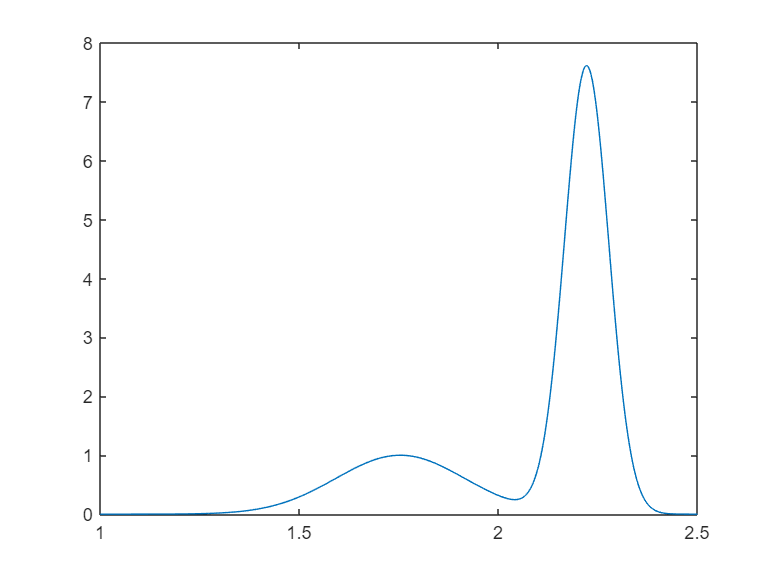

interference_signal = interference_signal-mean(interference_signal);
baoluo = hilbert(interference_signal); % Hilbert变换
baoluo = abs(baoluo);
% plot(z,interference_signal,z,baoluo,'--','linewidth',1);

% [pks,locs,w,p] = findpeaks(baoluo,z,'MinPeakProminence',max(baoluo)/10);
%修改BYration，观察波峰和波谷特征变化。
%BYration：0.6，0.7，0.8，0.9，1.0，1.1，1.2，1.3，1.4，1.5，1.6，1.7，1.8，1.9，2.0，2.1，2.2，2.3，2.4，2.5
%波峰位置：
%波峰幅度比值：
%波谷位置：
%波谷幅度比值
IndMin=find(diff(sign(diff(baoluo)))>0)+1;
IndMax=find(diff(sign(diff(baoluo)))<0)+1;
idx1 = find(z(IndMax)>15 & z(IndMax)<25);
idx2 = find(z(IndMin)>15 & z(IndMin)<25);
IndMax = IndMax(idx1);
IndMin = IndMin(idx2);
% hold on
% plot(z(IndMax),baoluo(IndMax),'xb','MarkerSize',8)
% plot(z(IndMin),baoluo(IndMin),'^r','MarkerSize',8)
bofengloc(n,:) = z(IndMax);
bofeng(n,:) = baoluo(IndMax);
boguloc(n,:) = z(IndMin);
bogu(n,:) = baoluo(IndMin);
end

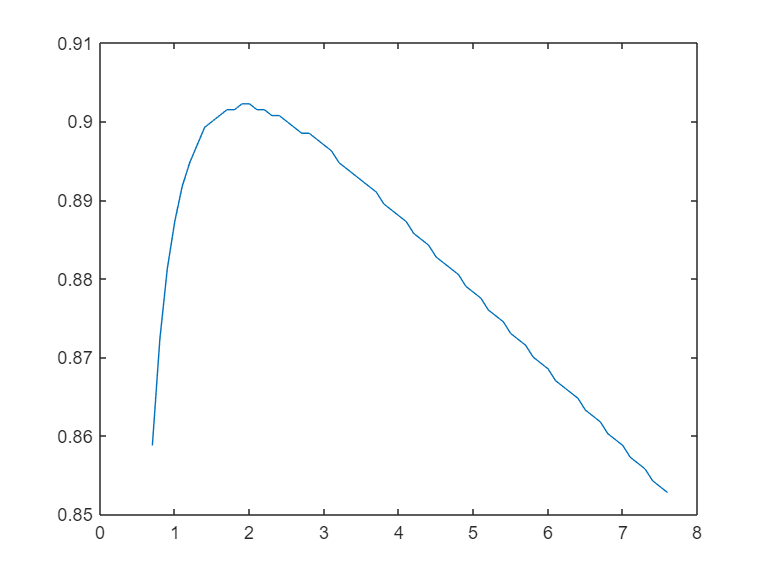

plot(0.6+0.1*(1:70),bofengloc(1:70,3)-bofengloc(1:70,2));%波峰位置

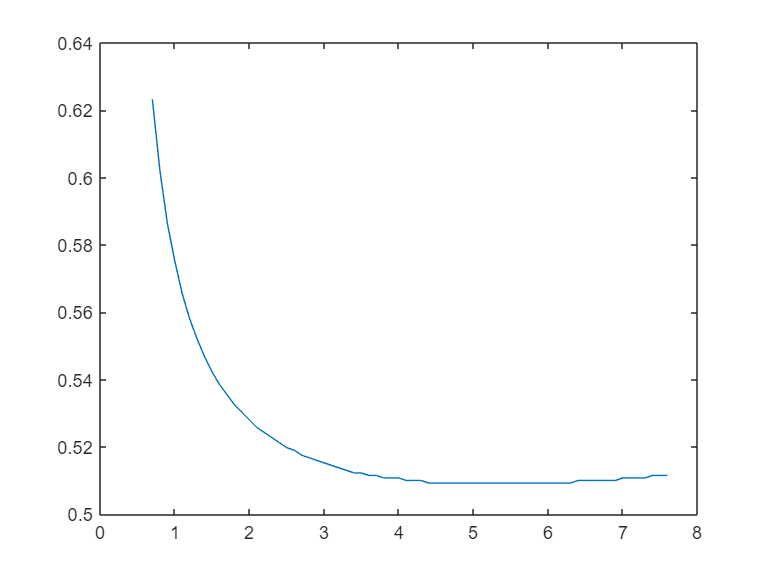

plot(0.6+0.1*(1:70),boguloc(1:70,2)-bofengloc(1:70,2));%波谷位置

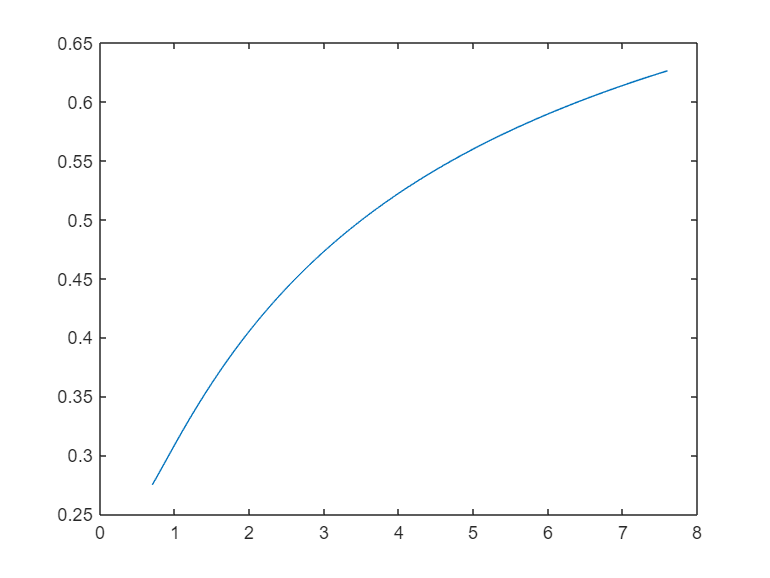

plot(0.6+0.1*(1:70),bofeng(1:70,3)./bofeng(1:70,2));%波峰幅度比值

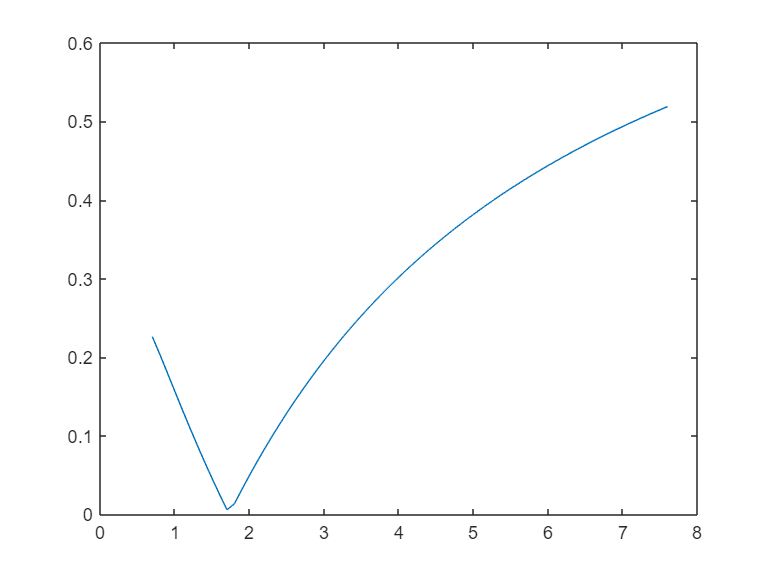

plot(0.6+0.1*(1:70),bogu(1:70,2)./bofeng(1:70,2));%波谷幅度比值